## ***Lab Exercise***

### ** Perform the following tasks.**

## *** Task 1: ***

Observe the frequency spectrum of the signal A?

-  t=0:1/8000:0.5;

-  A=sin(2*pi*440*(t)); 

Load chirp.mat and observe the frequency spectrum? 

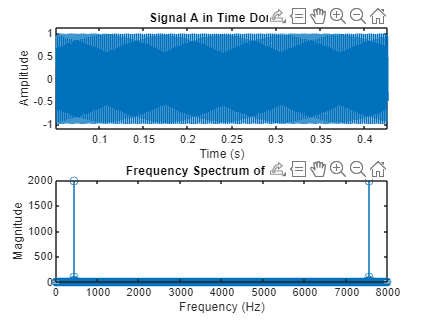

% Task 1: Observe the frequency spectrum of signal A
t = 0:1/8000:0.5;
A = sin(2*pi*440*t);

% Plot the time-domain signal
subplot(2, 1, 1);
plot(t, A);
ylim([-1.5 1.5])
title('Signal A in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');

% Compute and plot the frequency spectrum
A_fft = fft(A);
frequencies = linspace(0, 8000, length(A_fft));
subplot(2, 1, 2);
stem(frequencies, abs(A_fft));
title('Frequency Spectrum of Signal A');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

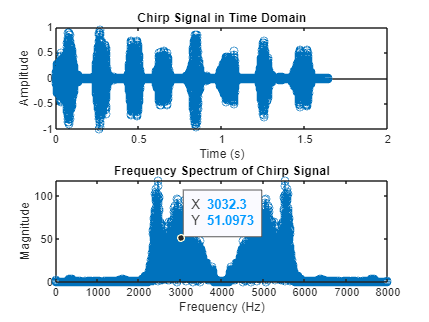


% Load chirp.mat and observe its frequency spectrum
load('chirp.mat');
dt = t(2) - t(1); % Define the sampling interval
t_chirp = 0:dt:(length(y)-1)*dt;
chirp_fft = fft(y);
frequencies_chirp = linspace(0, 1/dt, length(chirp_fft));
figure; % Open a new figure window
subplot(2, 1, 1);
stem(t_chirp, y);
title('Chirp Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');
subplot(2, 1, 2);
stem(frequencies_chirp, abs(chirp_fft));
title('Frequency Spectrum of Chirp Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

## ***Task 2: ***

Can we add signal A and chirp signal of Task 2, if yes then see the frequency spectrum of merged signal? 

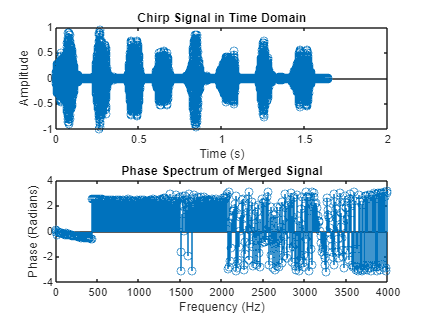

% Define the time vector for signal A
t = 0:1/8000:0.5;

% Create signal A
A = sin(2*pi*440*t);

% Load the chirp signal from chirp.mat
load chirp.mat; % Assuming 'y' is the chirp signal

% Convert 'y' from column to row vector if necessary
Z = y';

% Pad the shorter signal with zeros to make both signals the same length
if length(A) > length(Z)
    Z = [Z, zeros(1, length(A) - length(Z))];
elseif length(Z) > length(A)
    A = [A, zeros(1, length(Z) - length(A))];
end

% Add the two signals
mergedSignal = A + Z;
sound(mergedSignal, 8000);

% Define length of the FFT (nfft)
nfft = 1024;

% Compute the Fast Fourier Transform (FFT) of the merged signal
MergedX = fft(mergedSignal, nfft);

% Extract the first half of MergedX for positive frequencies
MergedX = MergedX(1:nfft/2+1);

% Calculate the magnitude of the FFT
mag_MergedX = abs(MergedX);

% Calculate the phase of the FFT
phase_MergedX = angle(MergedX);

% Frequency vector for plotting
f = (0:nfft/2)*8000/nfft;

% Plot the magnitude of the FFT
figure(1);
stem(f, mag_MergedX);
title('Magnitude Spectrum of Merged Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

% Plot the phase of the FFT
figure(2);
stem(f, phase_MergedX);
title('Phase Spectrum of Merged Signal');
xlabel('Frequency (Hz)');
ylabel('Phase (Radians)');

## ***Task 3: ***

Form a signal S containing a 50 Hz sinusoid of amplitude 0.7 and a 120 Hz sinusoid of amplitude 1. Corrupt the signal by adding noise. X = S + 2*randn(size(t)); Listen both signals and observe the frequency spectrum of both? 

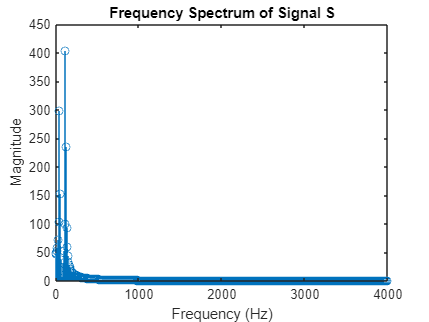


% Define the time vector for the signals
t = 0:1/8000:1;  % Assuming a duration of 1 second

% Form the signal S containing a 50 Hz sinusoid of amplitude 0.7 and a 120 Hz sinusoid of amplitude 1
S = 0.7 * sin(2*pi*50*t) + sin(2*pi*120*t);

% Corrupt the signal by adding noise
X = S + 2*randn(size(t));

% Listen to the original signal S
sound(S, 8000);

% Listen to the corrupted signal X
sound(X, 8000);

% Compute the Fast Fourier Transform (FFT) of the original signal S
nfft = 1024;
SX = fft(S, nfft);
mag_SX = abs(SX);
f_SX = (0:nfft/2)*8000/nfft;

% Compute the Fast Fourier Transform (FFT) of the corrupted signal X
X = X(:);  % Ensure X is a column vector
nfft = 1024;
X_fft = fft(X, nfft);
mag_X = abs(X_fft);
f_X = (0:nfft/2)*8000/nfft;

% Plot the frequency spectrum of the original signal S
figure;
stem(f_SX, mag_SX(1:nfft/2+1));
title('Frequency Spectrum of Signal S');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

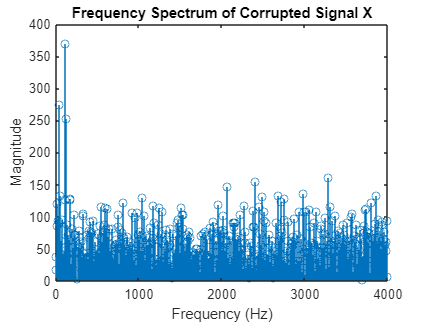


% Plot the frequency spectrum of the corrupted signal X
figure;
stem(f_X, mag_X(1:nfft/2+1));
title('Frequency Spectrum of Corrupted Signal X');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

## ***Task 4: ***

Find the discrete Fourier transform of the following signal (both phase and magnitude plot)? 

F=2cos(2*pi*15*(t)) + 5cos(2*pi*40*(t)) + 7cos(2*pi*70*(t)); 

Then convert Frequency domain signal into time domain signal using inverse fourier transform.

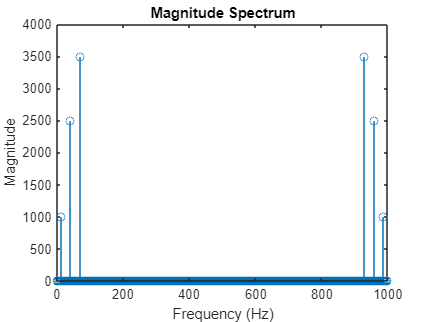

% Define the sampling frequency and time vector
Fs = 1000; % Sampling frequency in Hz
t = 0:1/Fs:1-1/Fs; % Time vector for 1 second

% Define the signal F
F = 2*cos(2*pi*15*t) + 5*cos(2*pi*40*t) + 7*cos(2*pi*70*t);

% Compute the DFT of the signal F
nfft = length(F); % Number of points in FFT
F_fft = fft(F, nfft); % DFT of signal F

% Compute the magnitude and phase of the DFT
mag_F_fft = abs(F_fft); % Magnitude
phase_F_fft = angle(F_fft); % Phase

% Frequency vector for plotting
f = (0:nfft-1)*Fs/nfft;

% Plot the magnitude spectrum
figure(1);
stem(f, mag_F_fft);
title('Magnitude Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

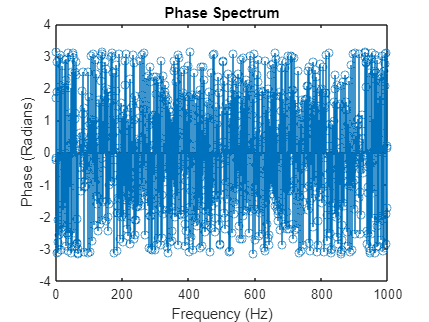

% Plot the phase spectrum
figure(2);
stem(f, phase_F_fft);
title('Phase Spectrum');
xlabel('Frequency (Hz)');
ylabel('Phase (Radians)');

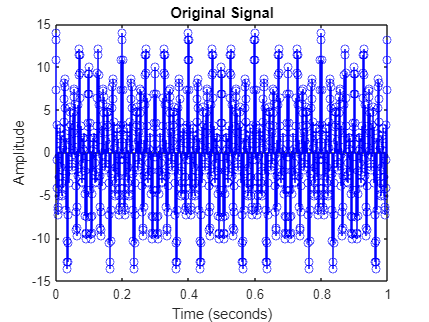


% Convert the frequency domain signal back to time domain using IFT
F_ift = ifft(F_fft, nfft);

% Plot the original and reconstructed signals to compare
figure(3);
stem(t, F, 'b');
title('Original Signal');
xlabel('Time (seconds)');
ylabel('Amplitude');

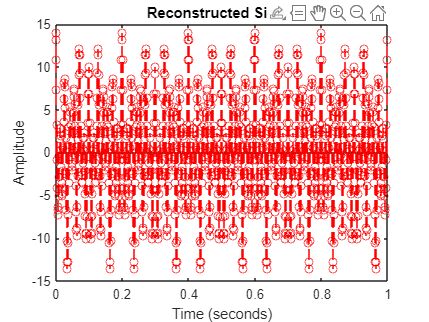

figure(4);
stem(t, F_ift, 'r--');
title('Reconstructed Signal');
xlabel('Time (seconds)');
ylabel('Amplitude');